# An Autopilot Designed To Maintain The Pitch Attitude $\theta$ Of An Aircraft 

## ECE 6200 - Fall 2024 

#### **Marim Mahmoud - T00401650 **

#### **Abdelrhman Elsayed - T00388057**

### Introduction

The **Boeing 747** is a large, wide-body, long-range commercial aircraft with complex **aerodynamic** and **motion dynamics** that are crucial for effective **control** and **stability**. Its motion is typically modeled using **linearized equations of motion**, which describe its behavior in both **longitudinal** and **lateral** directions. These equations are divided into two independent sets: longitudinal motion, which involves **axial**, **vertical**, and **pitching** movements, and lateral motion, which includes **rolling** and **yawing** movements. Longitudinal motion is primarily controlled by the **elevator** and **throttle**, which influence the aircraft's **pitch attitude** and **forward speed**. 

Our focus is on the longitudinal motion, particularly in the context of an **autopilot system** designed to maintain the aircraft's **pitch attitude **$\left(\theta \right)$. The pitch attitude is defined as the angular orientation of the aircraft's nose relative to the horizon.The autopilot ensures that the aircraft's pitch angle remains **stable** and within desired limits despite external disturbances or changes in flight conditions. This stability is achieved through careful adjustments of control surfaces, such as the **elevator**, and **engine power**, which regulate the aircraft’s attitude and stability. Modern aircraft rely on advanced **control systems** to automate pitch regulation, reducing **pilot workload** while enhancing operational performance across various conditions.

#### Objectives:

- Develop a mathematical model of the pitch control system in the form of state-space representation and transfer functions .

- Analyse the system for key properties such as controllability, observability, and stability.

- Design a state feedback controller to stabilize the pitch attitude by appropriately placing the system poles.

- Ensure that the controller meets desired performance criteria, such as settling time, overshoot, and steady-state error.

- Develop a state observer to estimate unmeasured states of the system, ensuring the controller operates effectively in the presence of partial measurements.

- Implement the designed controller and observer in MATLAB.

- Simulate the closed-loop system to validate its performance, stability, and robustness under different operating conditions.

### Problem Formulation

A schematic with the relevant coordinates that move with the Boeing 747 airplane is shown in the following figure.

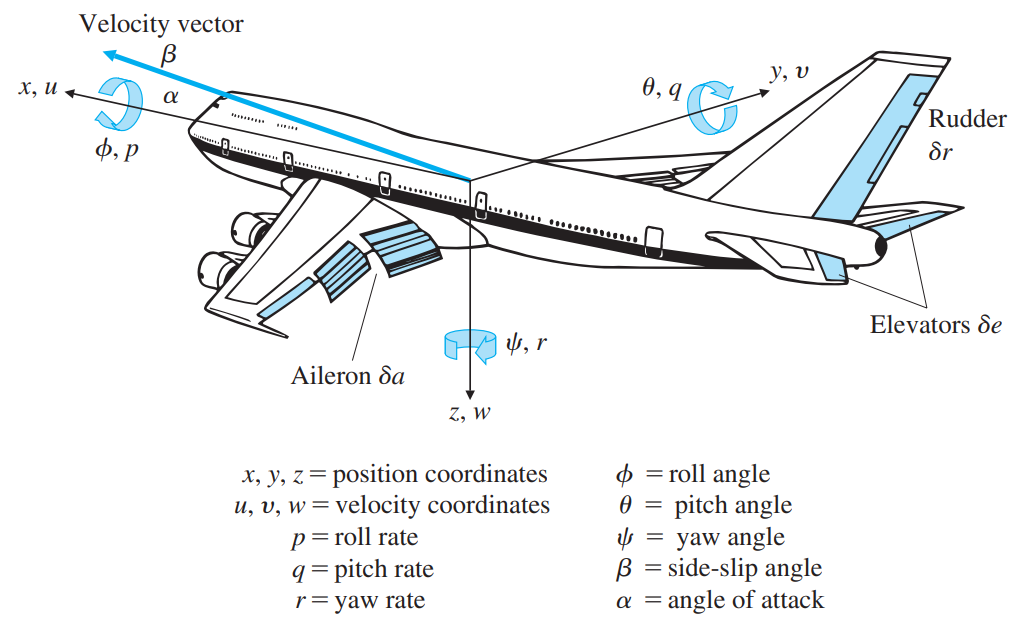

Here are the key equations related to the longitudinal motion of the Boeing 747, as described in the nonlinear rigid body equations of motion and their subsequent linearization in [1]:

**Nonlinear Equations of Motion:**

1. Longitudinal Dynamics:

    
$$\begin{array}{l}
m\left(\overset{\bullet }{U} +\textrm{qW}-\textrm{rV}\right)=X-\textrm{mg}\;\sin \left(\theta \right)+\textrm{kT}\;\cos \left(\theta \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)\;a\\
\begin{array}{l}
m\left(\overset{\bullet }{V} +\textrm{rU}-\textrm{pW}\right)=Y+\textrm{mg}\;\sin \left(\phi \right)\;\cos \left(\theta \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)\;b\\
m\left(\overset{\bullet }{W} +\textrm{pV}-\textrm{qU}\right)=Z+\textrm{mg}\;\cos \left(\phi \right)\;\cos \left(\theta \right)-\textrm{kT}\;\sin \left(\theta \right)\;\;\;\;\left(1\right)\;c
\end{array}
\end{array}$$


    (1) a: describes the perturbation in the $x-\textrm{axis}$ (forward velocity)

         b: describes the perturbation in the $y-\textrm{axis}$ (side velocity)

         c: describes the perturbation in the $z-\textrm{axis}$ (vertical velocity)

- **Perturbation** is a small disturbance or deviation from the equilibrium state. In the context of aircraft dynamics, it refers to changes like small variations in speed, altitude, pitch, or other flight variables from their nominal values due to control inputs or external disturbances.

2. Rotational Dynamics:

    
$$\begin{array}{l}
I_x \overset{\bullet }{p} +I_{\textrm{xz}} \overset{\bullet }{r} +\left(I_z -I_y \right)\textrm{qr}+I_{\textrm{xz}} \textrm{qp}=L\;\;\;\;\;\left(2\right)\;a\\
I_y \overset{\bullet }{p} +\left(I_x -I_z \right)\textrm{qr}+I_{\textrm{xz}} \left(r^2 -p^2 \right)=M\;\;\;\;\left(3\right)\;b\\
I_z \overset{\bullet }{r} +I_{\textrm{xz}} \overset{\bullet }{p} +\left(I_y -I_x \right)\textrm{qp}-I_{\textrm{xz}} \textrm{qr}=N\;\;\;\;\;\left(4\right)\;c
\end{array}$$


where,

- $m=$ mass of the aircraft, 

- $\left\lbrack \begin{array}{ccc}
U & V & W
\end{array}\right\rbrack =$ body-axis components of the velocity of the center of mass (c.m.), 

- $\left\lbrack \begin{array}{ccc}
p & q & r
\end{array}\right\rbrack =$ the body-axis components of the angular velocity of the aircraft, 

- $\left\lbrack \begin{array}{ccc}
X & Y & Z
\end{array}\right\rbrack =$ the body-axis aerodynamic forces about the c.m., 

- $\left\lbrack \begin{array}{ccc}
L & M & N
\end{array}\right\rbrack =$ the body-axis aerodynamic torques about the c.m., 

- $\left(\phi \;\textrm{and}\;\theta \right)=$ the Euler pitch and roll angles of the aircraft body, 

- $T=$ the propulsive thrust resultant, and 

- $k=$ the angle between thrust and body $x-\textrm{axis}$.

To measure the aircraft's pitch angle, the system typically uses **inertial sensors** (such as a **gyroscope** or **rate-integrating gyro**) or an **inertial reference system** (IRS). The **pitch rate **$q$, which is the rate of change of the pitch angle, is also measured for feedback purposes. The output sensors will provide the pitch angle, and the input will be the elevator deflection $\delta_e$, which controls the aircraft’s pitch attitude.

The primary actuator responsible for controlling the pitch angle $\theta$ is the elevator $\delta_e$, typically located on the horizontal tailplane of the aircraft. When the elevator is deflected, it generates a **pitching moment** that alters the aircraft's pitch rate $q$ and eventually stabilizes the pitch angle.

For purposes of altitude control, we assume the typical case of an elevator surface. The elevator deflection is controlled using **hydraulic actuators** due to their favorable force-to-weight ratio.

**The Steady-State Condition: **In steady-state flight (straight and level with constant speed), there are no accelerations or angular rates:

- 
$$\overset{\bullet }{U} =\overset{\bullet }{V} =\overset{\bullet }{W} =\overset{\bullet }{p} =\overset{\bullet }{q} =\overset{\bullet }{r} =0$$


- Assume no turning: $p_0 =q_0 =r_0 =0$

- Wings are level: $\phi =0$

- The aircraft maintains a certain **angle of attack** $\left(\theta \right)$ to balance the weight and lift.

The **steady-state velocities** are:

- 
$$U_0 =V_{\textrm{ref}} \;\cos \left(\theta_0 \right)$$


- 
$$V_0 =0$$


- 
$$W_0 =V_{\textrm{ref}} \;\sin \left(\theta_0 \right)$$


These steady-state conditions simplify the nonlinear equations, allowing for equilibrium (constant speed and level flight) conditions to be set:

- 
$$X_0 =\textrm{mg}\;\sin \left(\theta_0 \right)-\textrm{kT}\;\cos \left(\theta_0 \right)$$


- 
$$Y_0 =0$$


- 
$$Z_0 =-\textrm{mg}\;\cos \left(\theta \right)+\textrm{kT}\;\sin \left(\theta_0 \right)$$


- 
$$L_0 =0,\;M_0 =0,\;\textrm{and}\;N_0 =0$$


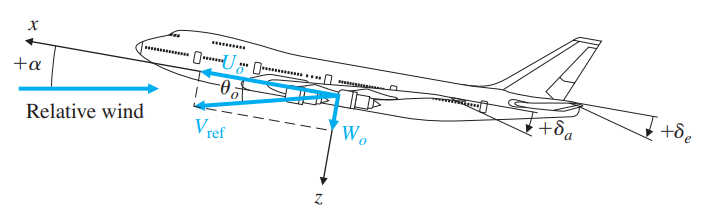

**Linearizing the Equations of Motion:**

Linearization is done by assuming that the perturbations from the steady-state condition are small. In other words, we consider small deviations in velocity components $u,v,w$, angular velocities $p,q,r$, and pitch angle $\theta$.

- The velocity perturbations are represented as: $U=U_0 +u$, $V=V_0 +v$, $W=W_0 +w$, where $u,v,w$, are small perturbations from the reference velocities.

The small angle assumptions (e.g.,$\theta^2 \ll 1,p^2 \ll 1$) allow us to neglect higher-order terms in the nonlinear equations.

**Apply Perturbation Theory:**

Substitute the linearized variables into the nonlinear equations. Since the perturbations are small, terms that involve squares of the perturbations (like $u^2 ,w^2$) or higher-order terms are neglected. This leads to the following simplified linear equations for the longitudinal motion:


$$\left\lbrack \begin{array}{c}
\overset{\bullet }{u} \\
\overset{\bullet }{w} \\
\overset{\bullet }{q} \\
\overset{\bullet }{\theta} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
X_u  & X_w  & -W_0  & -g_0 \;\cos \left(\theta_0 \right)\\
Z_u  & Z_w  & U_0  & -g_0 \;\sin \left(\theta_0 \right)\\
M_u  & M_w  & M_q  & 0\\
0 & 0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
w\\
q\\
\theta 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
X_{\delta_e } \\
Z_{\delta_e } \\
M_{\delta_e } \\
0
\end{array}\right\rbrack \left\lbrack \delta_e \right\rbrack$$


where,

- $u=$ forward velocity perturbation in the aircraft in $x$ direction, 

- $w=$  velocity perturbation in the $z$ direction (also proportional to perturbations in the angle of attack, $\alpha =\frac{w}{U_0 }$), 

- $q=$ angular rate about the positive $y-\textrm{axis}$, or pitch rate, 

- $\theta =$ pitch-angle perturbation from the reference $\theta_0$ value, 

- $X_{u,w,\delta_e } =$ partial derivative of the aerodynamic force in $x$ direction with respect to perturbations in$u,w,\delta_e$, 

- $Z_{u,w,\delta_e } =$ partial derivative of the aerodynamic force in $z$ direction with respect to perturbations in $u,w,\delta_e$, 

- $M_{u,w,q,\delta_e } =$ partial derivative of the aerodynamic (pitching) moment with respect to perturbations in $u,w,q,\delta_e$, and

- $\delta_e =$ movable tail-section, or “elevator,” angle for pitch control.

Finally, to determine how the pitch angle affects the altitude, the following equation is added to the longitudinal motion equations:


$$\overset{\bullet }{h} =V_{\textrm{ref}} \;\sin \left(\theta \right)-w\;\cos \left(\theta \right)$$


This is then linearized to give:


$$\overset{\bullet }{h} =V_{\textrm{ref}} \;\theta -w$$


This equation relates the altitude change to the pitch angle and vertical velocity, completing the linear model for the longitudinal motion.

The **output** we are interested in is the **altitude (h)**, which is related to the pitch angle. The output equation is:


$$y=C\left\lbrack \begin{array}{c}
u\\
w\\
q\\
\theta 
\end{array}\right\rbrack$$


This allows us to extract the pitch angle $\theta$ from the state vector.

To ensure the system behaves properly, the dynamic performance specifications are as follows:

- The **damping ratio **should be close to **0.5** for stability and smooth response.

- The **natural frequency **should be slow (e.g., **1 rad/sec**) to ensure a smooth ride.

- The system should maintain precise control over the pitch angle despite external disturbances, such as turbulence or variations in engine thrust.

### Mathematical Modelling

**Considering the x and y directions only and ignore the vertical velocity **$w$** for simplicity**, the system will have the following parameters: The forward velocity perturbation $u\;\left(\textrm{in}\;\frac{\textrm{ft}}{\sec }\right)$, the effect on longitudinal acceleration is approximatly $-0\ldotp 313$, indicating how changes in forward velocity influence acceleration. The pitch rate perturbation $q\;\left(\textrm{in}\;\frac{\textrm{radians}}{\sec }\right)$ influences longitudinal acceleration with a factor of $56\ldotp 7$, due to the aircraft's moment arm and aerodynamic characteristics. The movable tail-section (force), or “elevator,” angle for pitch control is affecting the forward velocity perturbation by a factor of $0\ldotp 232$. The following state-space representation of the system contain the rest of the numerical values:


$$\overset{\bullet }{x} =\left\lbrack \begin{array}{ccc}
-0\ldotp 313 & 56\ldotp 7 & 0\\
-0\ldotp 0139 & -0\ldotp 426 & -5\\
0 & 56\ldotp 7 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\ldotp 232\\
0\ldotp 0203\\
0
\end{array}\right\rbrack \left\lbrack \delta_e \right\rbrack$$


Therefore, the state matrix is as follows:


$$A=\left\lbrack \begin{array}{ccc}
-0\ldotp 313 & 56\ldotp 7 & 0\\
-0\ldotp 0139 & -0\ldotp 426 & -5\\
0 & 56\ldotp 7 & 0
\end{array}\right\rbrack$$


The **output** we are interested in is the pitch angle. The output equation is:


$$y=\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x
\end{array}\right\rbrack$$


% System Equations
A = [-0.313 56.7 0; -0.0139 -0.426 -5; 0 56.7 0];
B = [0.232; 0.0203; 0];
C = [0 0 1];
D = [0];

**Getting The Transfer Function: **$C{\left(\textrm{sI}-A\right)}^{-1} B$


$$\begin{array}{l}
\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack {\left(\left\lbrack \begin{array}{ccc}
s & 0 & 0\\
0 & s & 0\\
0 & 0 & s
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
-0\ldotp 313 & 56\ldotp 7 & 0\\
-0\ldotp 0139 & -0\ldotp 426 & -5\\
0 & 56\ldotp 7 & 0
\end{array}\right\rbrack \right)}^{-1} \left\lbrack \begin{array}{c}
0\ldotp 232\\
0\ldotp 0203\\
0
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack {\left(\left\lbrack \begin{array}{ccc}
s+0\ldotp 313 & -56\ldotp 7 & 0\\
0\ldotp 0139 & s+0\ldotp 426 & 5\\
0 & -56\ldotp 7 & s
\end{array}\right\rbrack \right)}^{-1} \left\lbrack \begin{array}{c}
0\ldotp 232\\
0\ldotp 0203\\
0
\end{array}\right\rbrack 
\end{array}$$


% Getting the transfer function
[num,den] = ss2tf(A,B,C,D)

num =          0         0    1.1510    0.1774


den =     1.0000    0.7390  284.4215   88.7355


G = tf(num,den);

Therefore, the `Continuous-time transfer function is:`


$$\frac{\theta \left(s\right)}{\delta_e \left(s\right)}=G\left(s\right)=\frac{1\ldotp 151s+0\ldotp 1774}{s^3 +0\ldotp 739s^2 +284\ldotp 4215s+88\ldotp 7355}$$


### System Analysis

**1. Stability Analysis**

Internal stability check:


$$\left|A-\lambda I\right|=\left|\left\lbrack \begin{array}{ccc}
-0\ldotp 313-\lambda  & 56\ldotp 7 & 0\\
-0\ldotp 0139 & -0\ldotp 426-\lambda  & -5\\
0 & 56\ldotp 7 & -\lambda 
\end{array}\right\rbrack \right|$$


% Getting the eignvalues
e = eig(A)

e =   -0.3121 + 0.0000i
  -0.2134 +16.8595i
  -0.2134 -16.8595i


It is observed that the eigenvalues have negative real parts. Thus, the system is internally stable, which implies BIBO stability.

**2. Controllability Analysis**


$$\mathrm{CO}=\left\lbrack \begin{array}{ccc}
B & \mathrm{AB} & {\mathrm{A}}^2 B
\end{array}\right\rbrack$$


CO = ctrb(A,B)

CO =     0.2320    1.0784   -1.0107
    0.0203   -0.0119   -5.7650
         0    1.1510   -0.6732


rank(CO)

ans = 3

It can be observed from the echolen form that controllability matrix has rank of 3 which is full row rank. Thus, the system is controllable.

**3. Observability Analysis**


$$\textrm{OB}=\left\lbrack \begin{array}{c}
C\\
\textrm{CA}\\
C{\mathrm{A}}^2 
\end{array}\right\rbrack$$


OB = obsv(A,C)

OB =          0         0    1.0000
         0   56.7000         0
   -0.7881  -24.1542 -283.5000


rank(OB)

ans = 3

It can be observed that the observability matrix in reduced echelon form has full column rank of 3. Henceforth, the system is observable.

**4. State feedback controller**


$$Q:=P^{-1} =\left\lbrack \begin{array}{ccc}
B & \textrm{AB} & {\mathrm{A}}^2 B
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & \alpha_1  & \alpha_2 \\
0 & 1 & \alpha_1 \\
0 & 0 & 1
\end{array}\right\rbrack$$


P_inv = CO * [1 den(1,2) den(1,3); 0 1 den(1,2);0 0 1]

P_inv =     0.2320    1.2498   65.7720
    0.0203    0.0031   -0.0000
         0    1.1510    0.1774


P = P_inv^-1

P =     0.0004   49.2569   -0.1343
   -0.0024    0.0269    0.8713
    0.0152   -0.1743   -0.0161



$$\overset{-}{A} =\textrm{PA}{\mathrm{P}}^{-1}$$


A_bar = P * A * P_inv

A_bar =    -0.7390 -284.4215  -88.7355
    1.0000    0.0000   -0.0000
    0.0000    1.0000   -0.0000



$$\overset{-}{B} =\textrm{PB}$$


B_bar = P * B

B_bar =      1
     0
     0


So, the new eignvalues are:

e_bar = eig(A_bar)

e_bar =   -0.2134 +16.8595i
  -0.2134 -16.8595i
  -0.3121 + 0.0000i


The desired feedback polynomial:


$$\overset{-}{K} =\left\lbrack {\overset{-}{a} }_1 -a_1 \;\;\;\;{\overset{-}{a} }_2 -a_2 \;\;\;\;{\overset{-}{a} }_3 -a_3 \right\rbrack$$


% Getting the new characteristic polynomial equation
syms eign
new_ch_po = (eign - e_bar(3,1)) * (eign - e_bar(2,1)) * (eign - e_bar(1,1))

$$new\_ch\_po = \left(\mathrm{eign}+\frac{1922441828110597}{9007199254740992}-\frac{4745526823341827}{281474976710656}\,\mathrm{i}\right)\,\left(\mathrm{eign}+\frac{1922441828110597}{9007199254740992}+\frac{4745526823341827}{281474976710656}\,\mathrm{i}\right)\,\left(\mathrm{eign}+\frac{5622873186064799}{18014398509481984}\right)$$

expand(new_ch_po)

$$ans = {\mathrm{eign}}^{3}+\frac{13312640498507187\,{\mathrm{eign}}^{2}}{18014398509481984}+\frac{5768752714047913982135502111737677\,\mathrm{eign}}{20282409603651670423947251286016}+\frac{129687078539376570164034473258098471462090609308295}{1461501637330902918203684832716283019655932542976}$$

d1 = 1

d1 = 1

d2 = 13312640498507187/18014398509481984

d2 = 0.7390

d3 = 5768752714047913982135502111737677/20282409603651670423947251286016

d3 = 284.4215

d4 = 129687078539376570164034473258098471462090609308295/1461501637330902918203684832716283019655932542976

d4 = 88.7355

So, the desired feedback polynomial will be: $\Delta_f \left(s\right)=s^3 +{\overset{-}{\alpha} }_1 s^2 +{\overset{-}{\alpha} }_2 s+{\overset{-}{\alpha} }_3 =s^3 +0\ldotp 739s^2 +284\ldotp 4215s+88\ldotp 7355$

K_b = [d2-den(1,2) d3-den(1,3) d4-den(1,4)]

K_b = 1.0e-12 *

    0.0024    0.7390    0.3126


The actual feedback gain applied to the original system is:


$$K=\overset{-}{K} P$$


K = K_b * P

K = 1.0e-12 *

    0.0030    0.0857    0.6385


**5. Tracking Reference Signal - Feedforward Gain**

% Getting Kf
syms x1 x2 x3 kf s L


$$\overset{\bullet }{X} =\left(A-\mathrm{BK}\right)X+BK_f$$


X_d = (A-B*K)*[x1; x2; x3] + B*kf

$$X\_d = \left(\begin{array}{c} \frac{29\,\mathrm{kf}}{125}-\frac{313\,x_{1}}{1000}+\frac{567\,x_{2}}{10}-\frac{1467004581238105\,x_{3}}{9903520314283042199192993792}\\ \frac{203\,\mathrm{kf}}{10000}-\frac{139\,x_{1}}{10000}-\frac{213\,x_{2}}{500}-5\,x_{3}\\ \frac{567\,x_{2}}{10} \end{array}\right)$$

G(s) = C${\left(\textrm{SI}-\left(A-\textrm{BK}\right)\right)}^{-1}$$BK_f$

Gs = C*inv(s*eye(3)-(A-B*K))*B*kf

$$Gs = \mathrm{kf}\,\left(\frac{142488136461786555021164097306624\,\left(1000\,s+313\right)}{25\,\left(4951760157141521099596496896000000\,s^{3}+3659350756127584092601811206144000\,s^{2}+1408386893078102114900209854817763328\,s+439396913424030867438084644721161175\right)}-\frac{22635258249358092740504925172137984}{25\,\left(4951760157141521099596496896000000\,s^{3}+3659350756127584092601811206144000\,s^{2}+1408386893078102114900209854817763328\,s+439396913424030867438084644721161175\right)}\right)$$

Gs = subs(Gs,s,0)

$$Gs = \frac{38736381769278834181868496093184\,\mathrm{kf}}{19373761614816175812966695093525625}$$

kf = 19373761614816175812966695093525625/38736381769278834181868496093184

kf = 500.1438

The following picture shows the State feedback controller simulation:

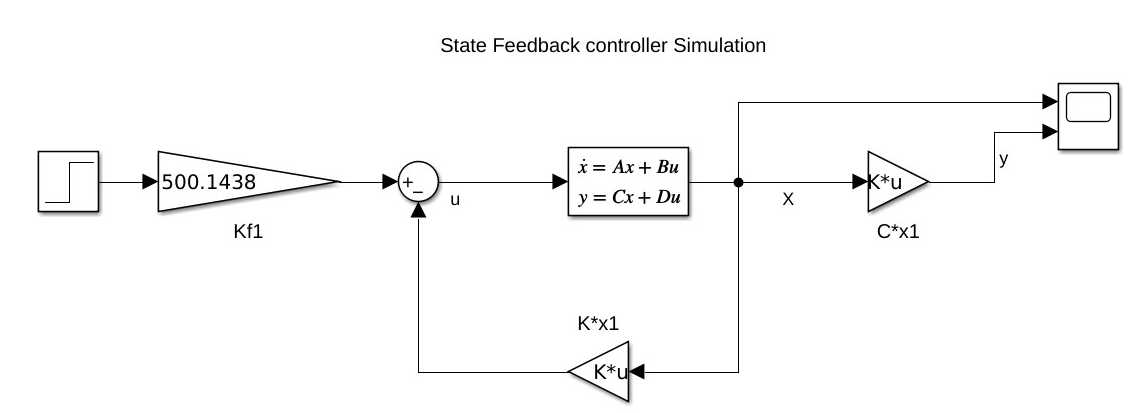

The state feedback output is shown in the following two pictures:

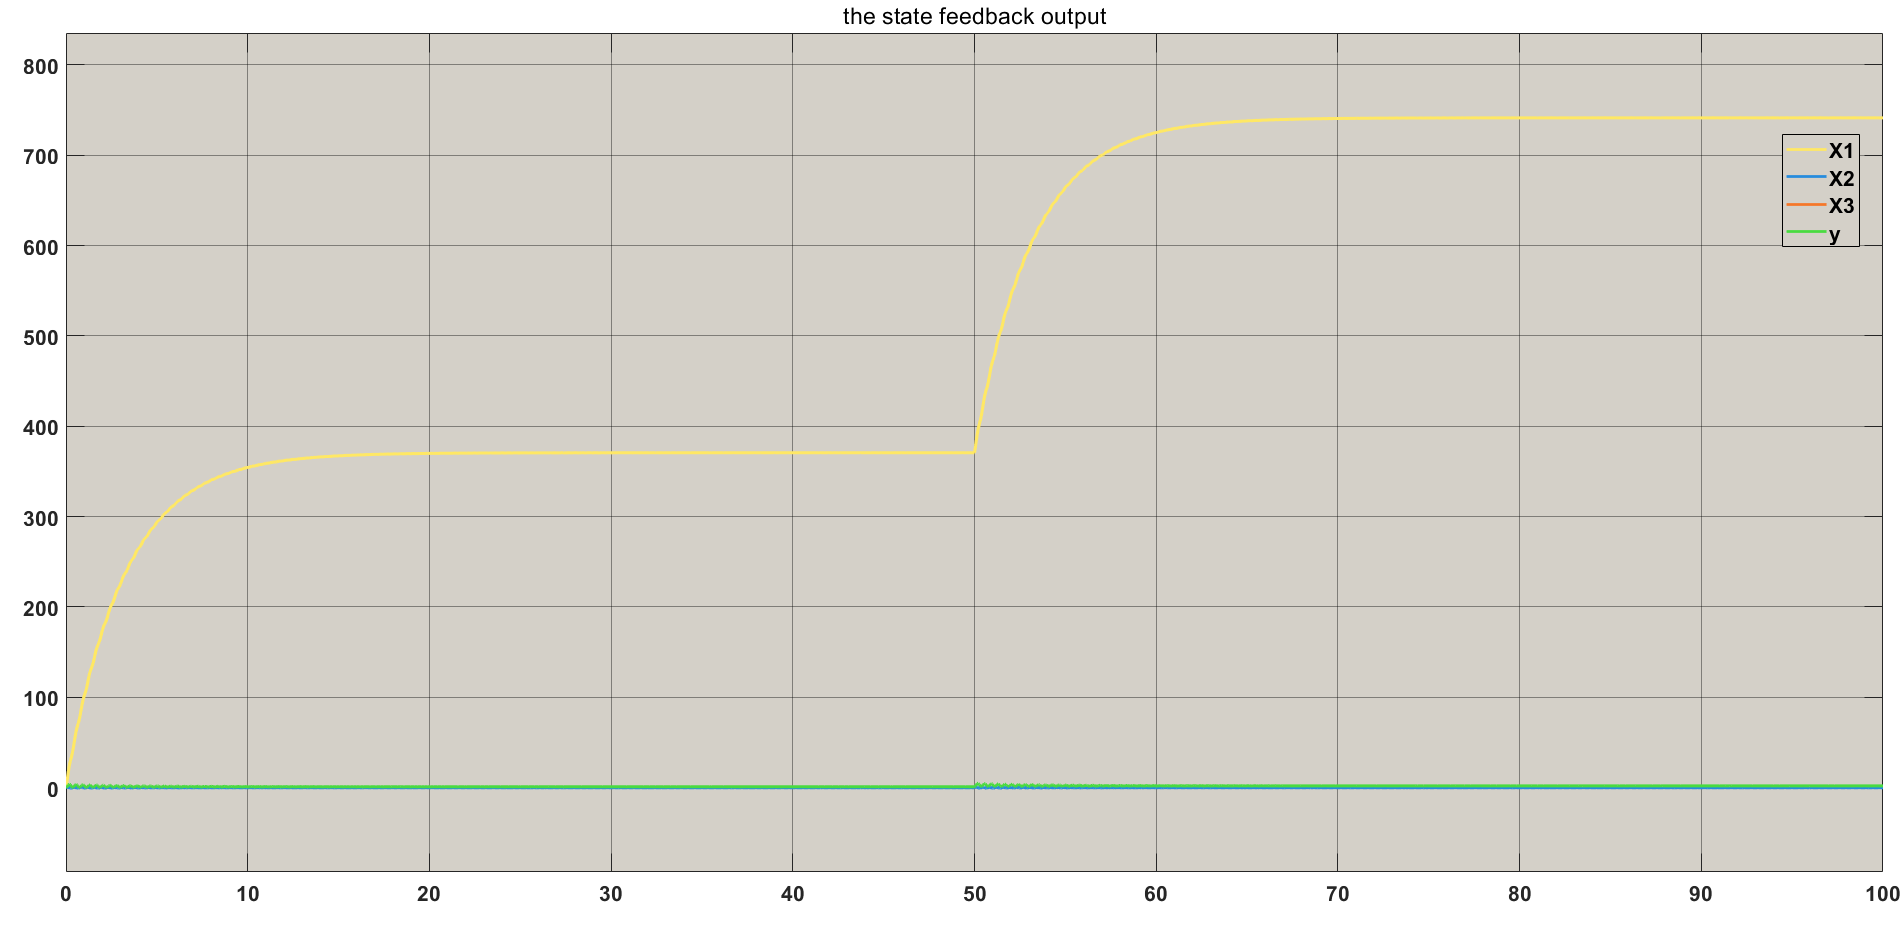

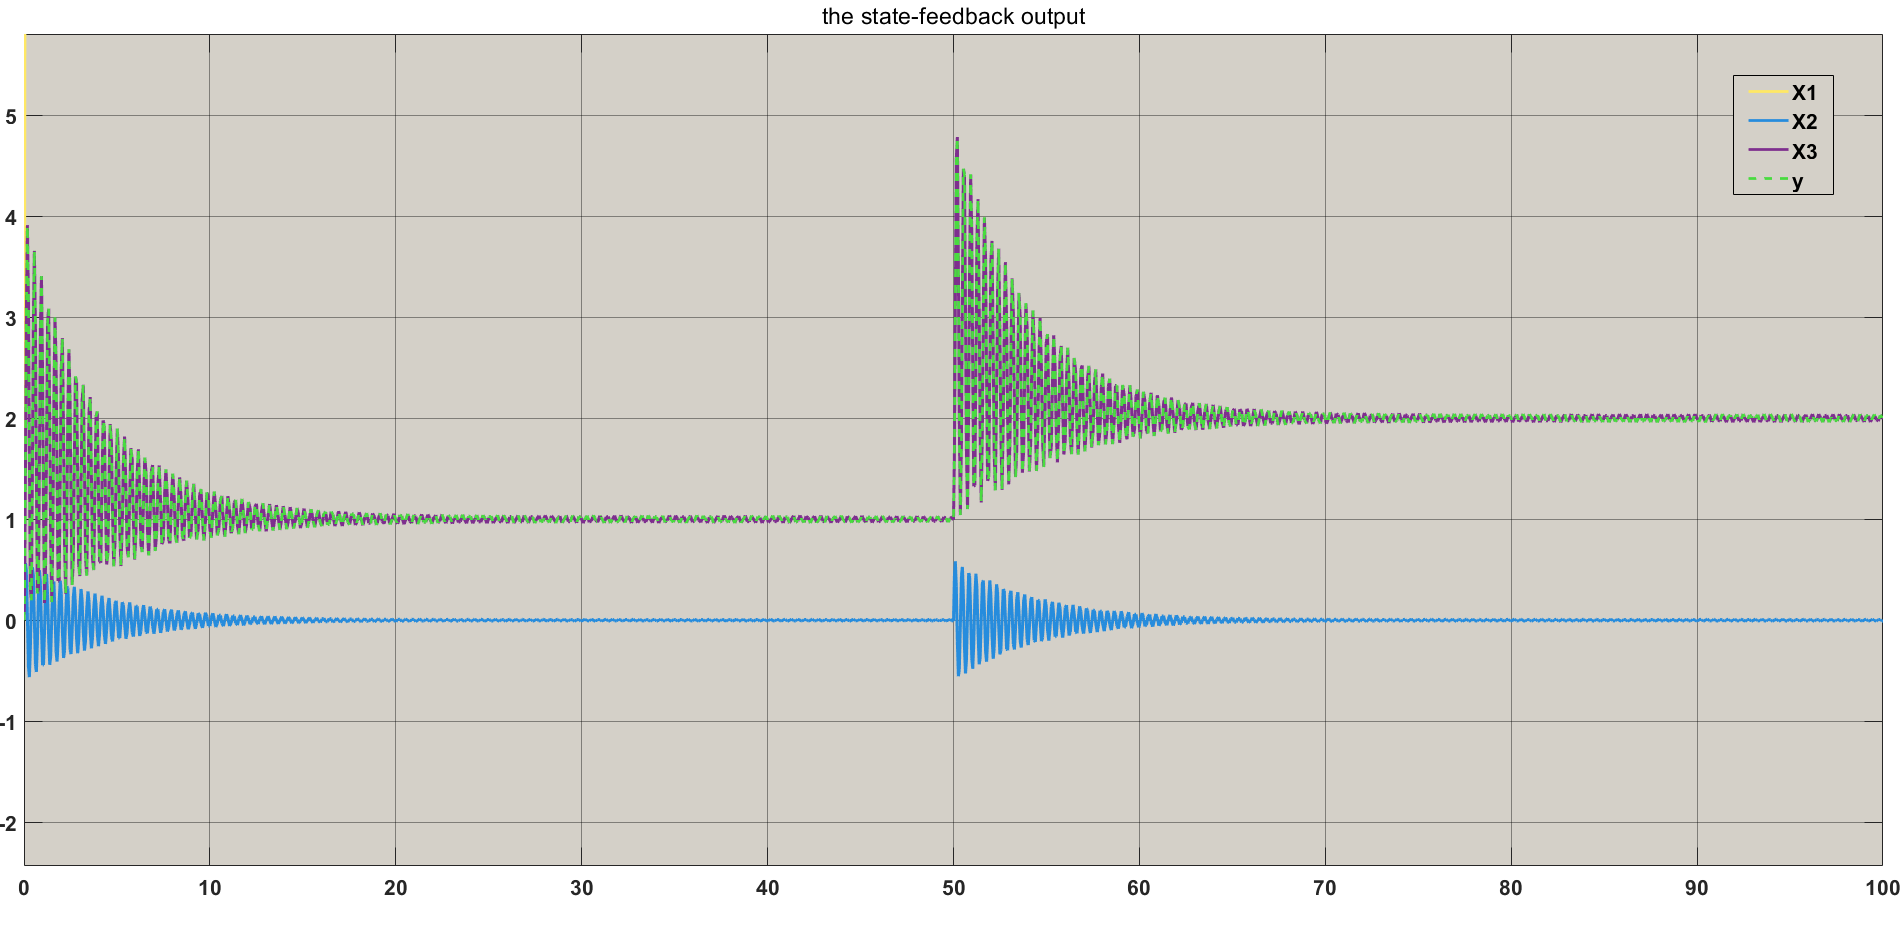

Notice that: the reference begins at 1 when time is 0, then changes to 2 at time 50. The output tracks the reference, and the output y matches the value of $\textrm{x3}$, which represents $\theta$.

**6. State Estimator (Observer)**


$$\mathrm{sI}-\left(A-\mathrm{LC}\right)=0$$


L = place(A',C',[-10 -20 -30])'

The design of state feedback control and estimator is shown in the following picture.

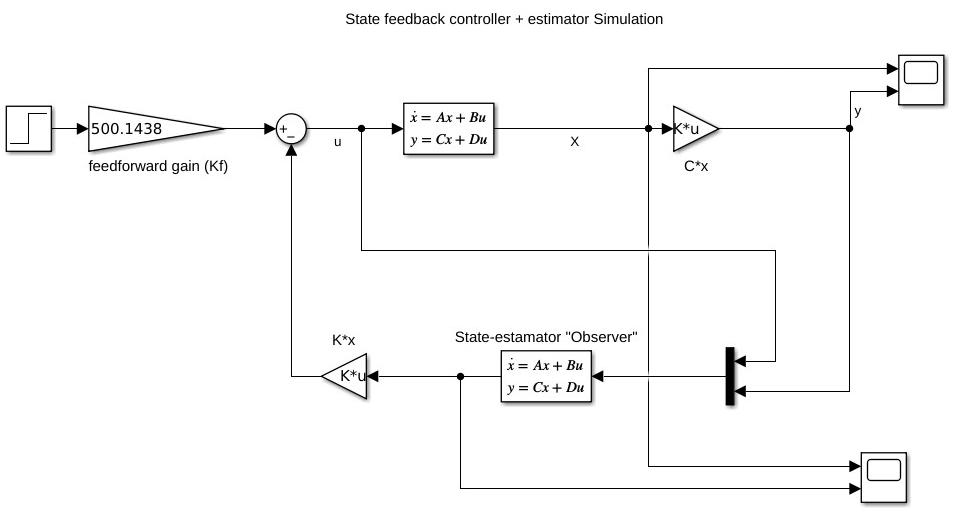

The results of the state estimator with the feedback control:

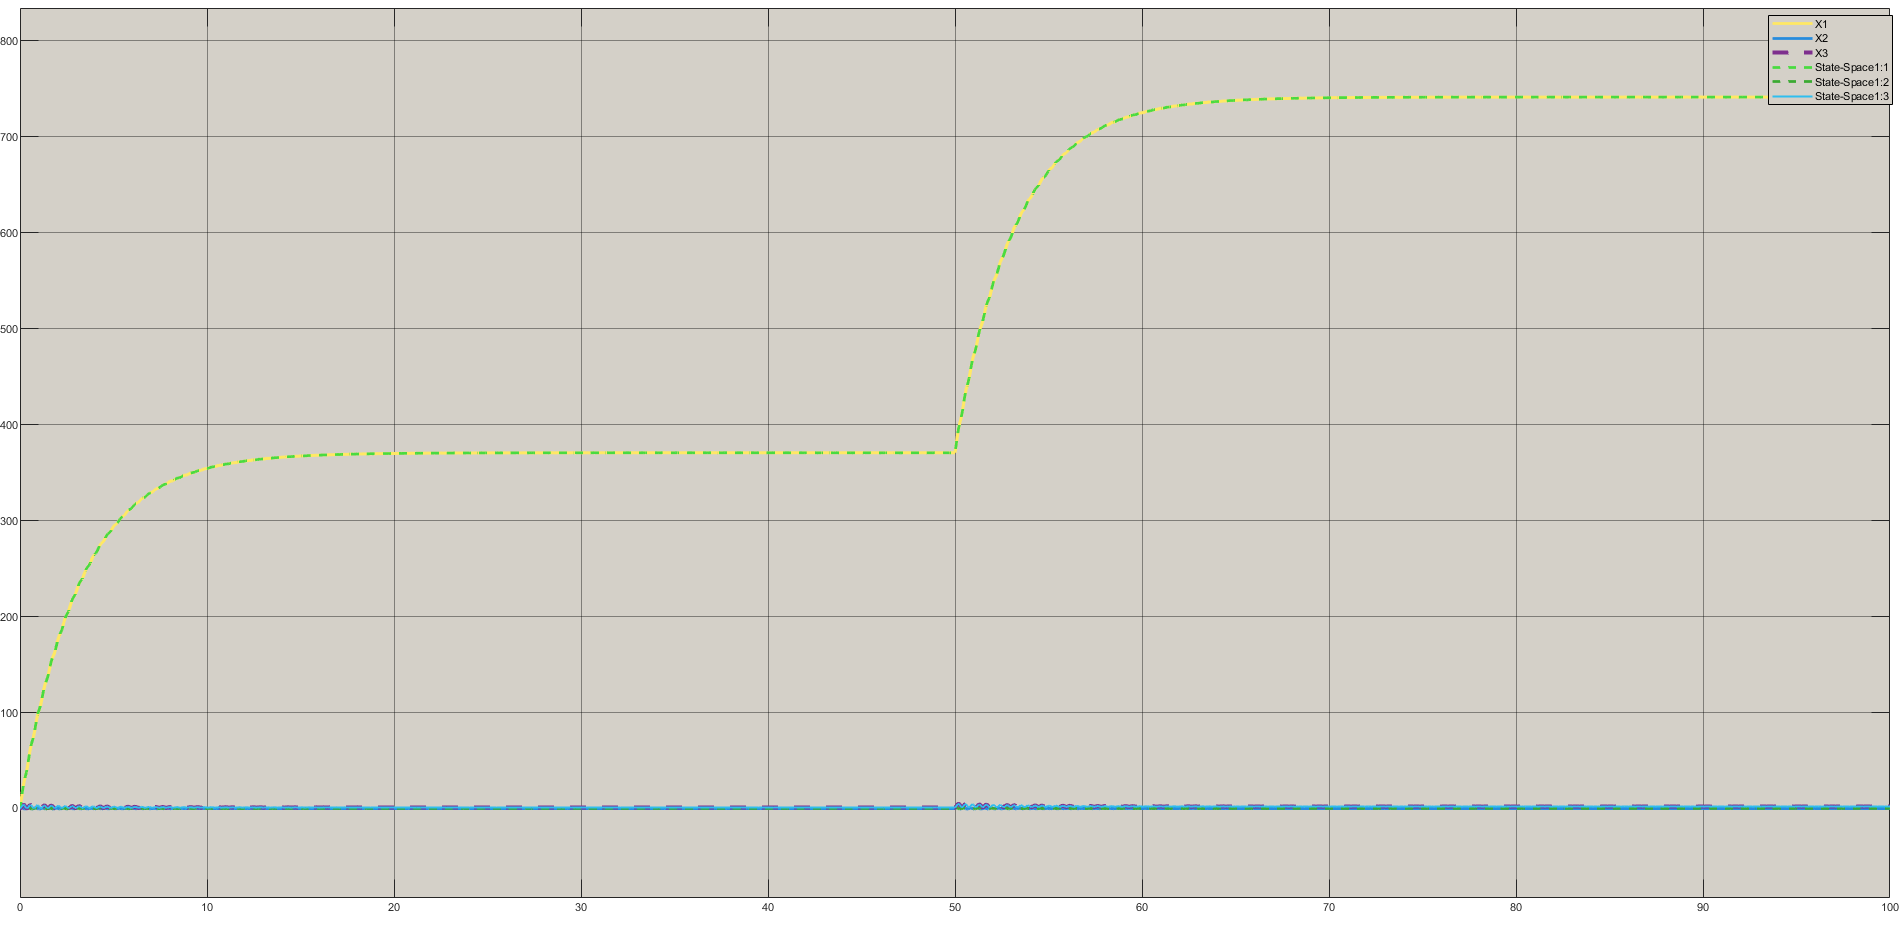

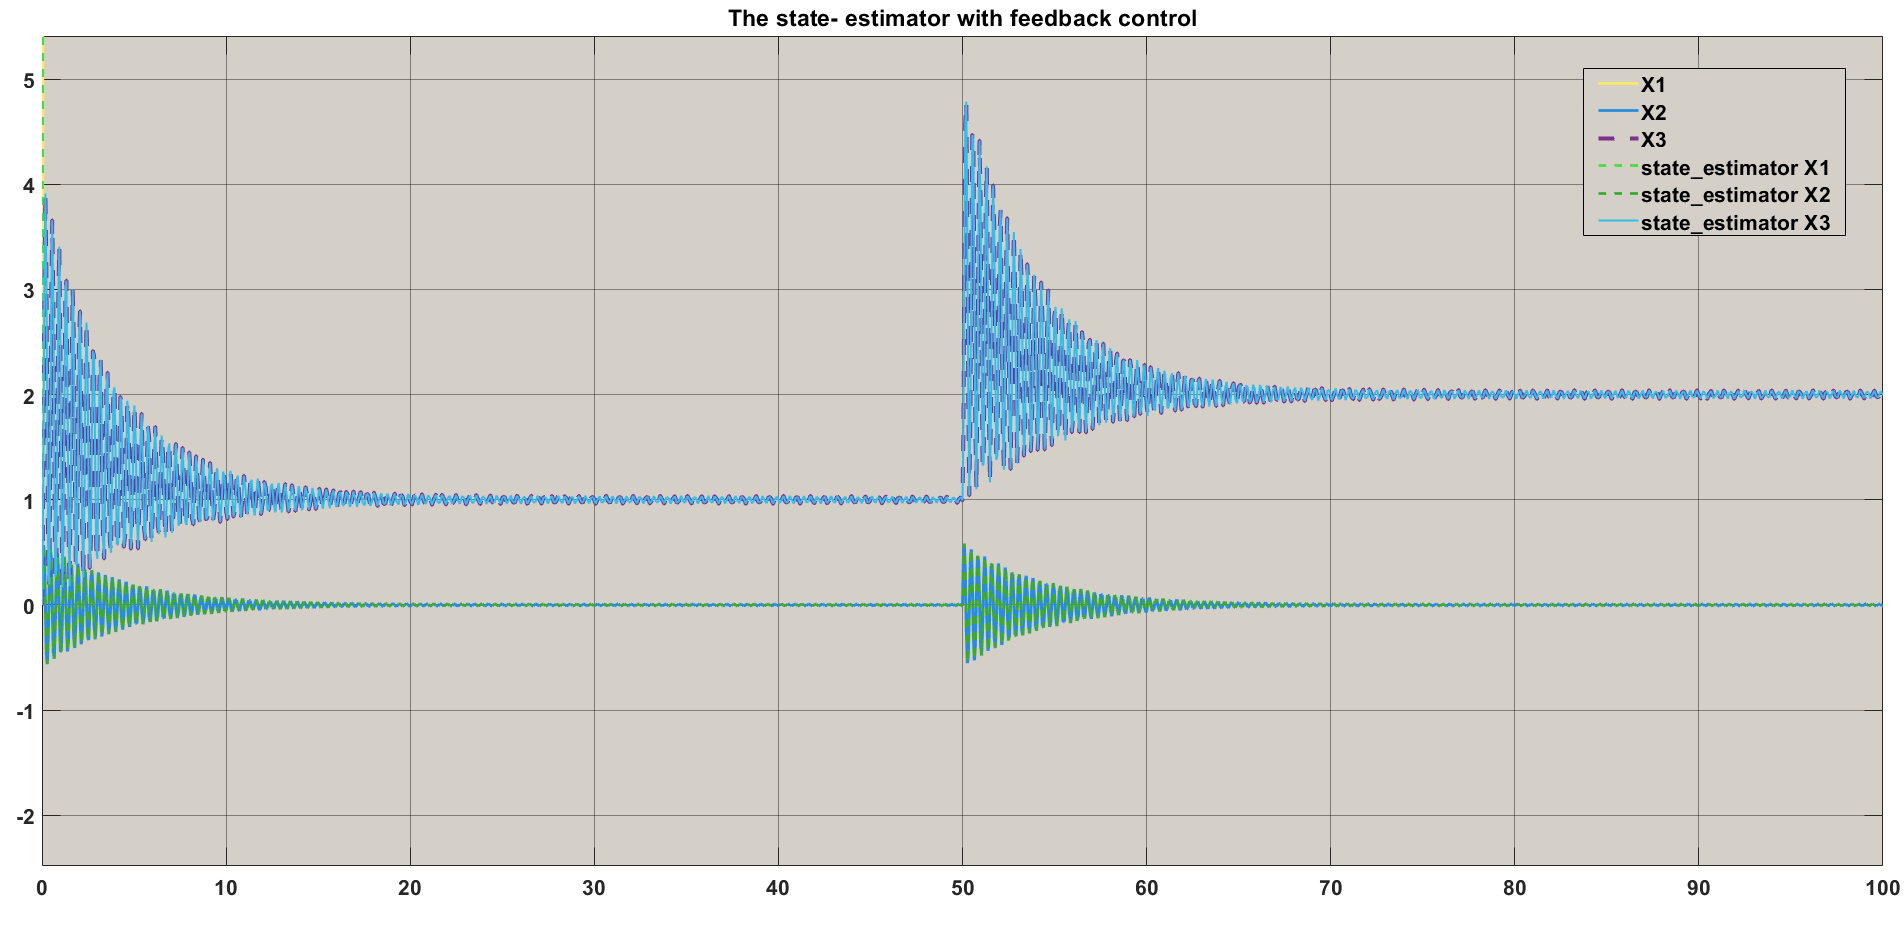

Notice that: the estimator design is verified because the output of the state estimator tracks the reference, and matches the values of the system.

### Conclusion

It was found that the system can be linearized to simplify the mathematical calculations and controller design. Moreover, internal stability showed that the system is inherently stable and implied BIBO stability of system. Additionally, controllability study showed that the system state variables are controllable. Moreover, observability analysis proved that the system is observable in which it is used to design state estimator. Finally, a simulation setup verified the controller and estimator design of the system.

**References:**

[1] Bryson, A. E., Jr., Control of Spacecraft and Aircraft. Princeton, NJ: Princeton University Press, 1994.

[2] Franklin, Gene F., J. David Powell, Abbas Emami-Naeini, and J. David Powell. *Feedback control of dynamic systems*. Vol. 4. Upper Saddle River: Prentice hall, 2002.